# Problem 7

hold off;

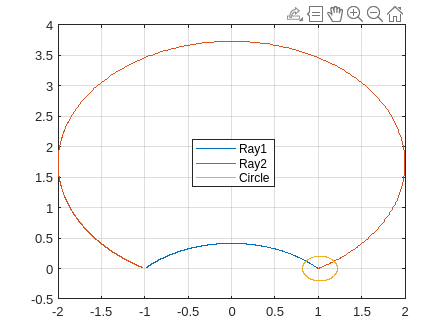

Ray = [0:.01:200]*exp(j*3*pi/4);
z = (2+Ray)./(2-Ray);
figure(1);
plot(z);grid;
hold on;

Ray = [0:.01:200]*exp(j*pi/6);
z = (2+Ray)./(2-Ray);
figure(1);
plot(z);
hold on;

theta = 0:.01:2*pi;
Circle = .2*cos(theta)+.2*j*sin(theta);
Zcircle = (2+Circle)./(2-Circle);
figure(1);
plot(Zcircle);
legend("Ray1","Ray2","Circle");

## Problem 3

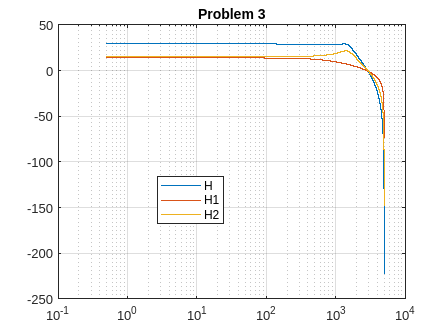


n1=[1 1];
d1=[1 -0.5977];

n2=[1 2 1];
d2=[1 -0.9827 0.6665];

k = 0.0018;

[H1,w]=freqz(n1,d1,10000);
H2=freqz(n2,d2,10000);
H=H1.*H2;
w=w/2/pi*10000;

H1db=20*log10(abs(H1));
H2db=20*log10(abs(H2));
Hdb=20*log10(abs(H));

figure(2);
semilogx(w,Hdb,w,H1db,w,H2db);grid;
title("Problem 3");
legend("H","H1","H2");

## Problem 4

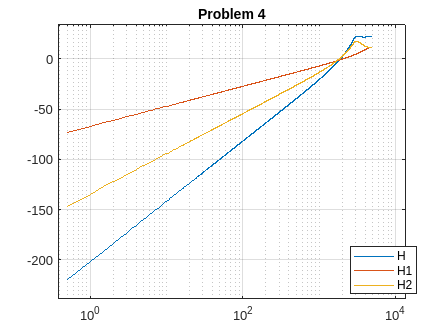

n1=[1 -1];
n2=[1 -2 1];
d1=[1 0.4716];
d2=[1 0.5045 0.6188];

k = 735.99;

[H1,w]=freqz(n1,d1,10000);
H2=freqz(n2,d2,10000);
H=H1.*H2;
w=w/2/pi*10000;

H1db=20*log10(abs(H1));
H2db=20*log10(abs(H2));
Hdb=20*log10(abs(H));

figure(3);
semilogx(w,Hdb,w,H1db,w,H2db);grid;
title("Problem 4");
legend("H","H1","H2");

## Problem 5

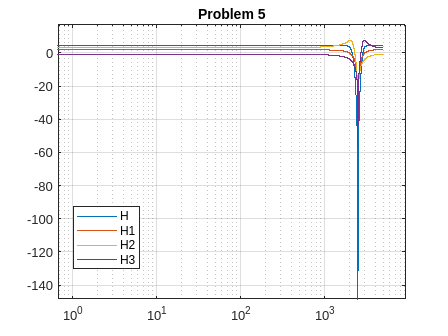

n=[1 0 1];

d1=[1 0 0.588];
d2=[1 -0.393 0.78];
d3=[1 0.393 0.78];

k = 0.5996;

[H1,w]=freqz(n,d1,10000);
H2=freqz(n,d2,10000);
H3=freqz(n,d3,10000);
H=H1.*H2.*H3;
w=w/2/pi*10000;

H1db=20*log10(abs(H1));
H3db=20*log10(abs(H3));
H2db=20*log10(abs(H2));
Hdb=20*log10(abs(H));

figure(4);
semilogx(w,Hdb,w,H1db,w,H2db,w,H3db);grid;
title("Problem 5");
legend("H","H1","H2","H3");

## Problem 6

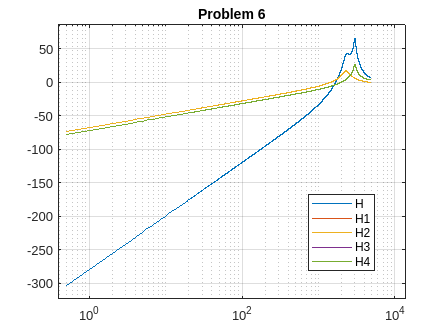

n=[1 -1];

d1=[1 -0.238 0.805];
d2=[1 -0.238 0.805];
d3=[1 0.585 0.921];
d4=[1 0.585 0.921];

k = 0.0021;

[H1,w]=freqz(n,d1,10000);
H2=freqz(n,d2,10000);
H3=freqz(n,d3,10000);
H4=freqz(n,d4,10000);
H=H1.*H2.*H3.*H4;
w=w/2/pi*10000;

H1db=20*log10(abs(H1));
H3db=20*log10(abs(H3));
H2db=20*log10(abs(H2));
H4db=20*log10(abs(H4));
Hdb=20*log10(abs(H));

figure(5);
semilogx(w,Hdb,w,H1db,w,H2db,w,H3db,w,H4db);grid;
title("Problem 6");
legend("H","H1","H2","H3","H4");

## FUCKER

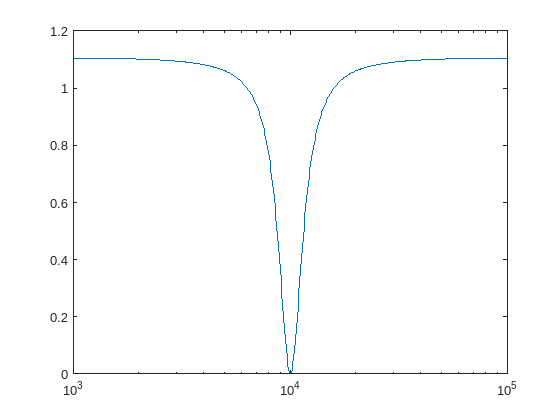

n=[1 0 1];
d=[1 0 0.81];

H=freqz(n,d);
Hdb=20*log10(abs(H));
figure(6);
w=logspace(3,5,512);
semilogx(w,H);

## Example pole 0 plot

num1=[1 2 1];
num2=[1 2 1];
numtotal=poly([-1 -1 -1 -1]); %generates a polynomial with 4 roots at "-1"
den1=[1 -1.4996 0.8482];
den2=[1 -1.5548 0.6493];
dentotal=conv(den1,den2);
[H1,w]=freqz(num1,den1,1024);
[H2,w]=freqz(num2,den2,1024);
K=(10^(-1/20))*(1/485.597);
H=K*H1.*H2;
figure(7);
plot(w/(2*pi),20*log10(abs(H)));grid;

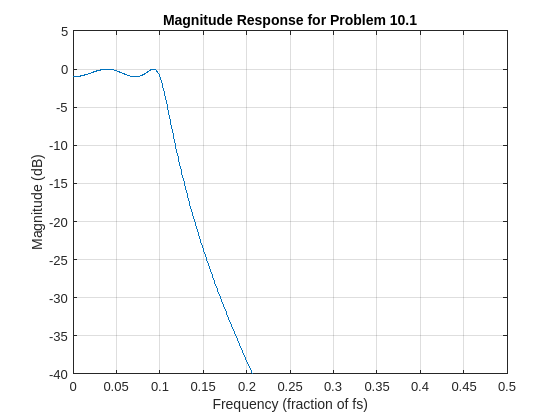

scale=[0,0.5,-40,5];axis(scale);
xlabel('Frequency (fraction of fs)');
ylabel('Magnitude (dB)');
title('Magnitude Response for Problem 10.1');

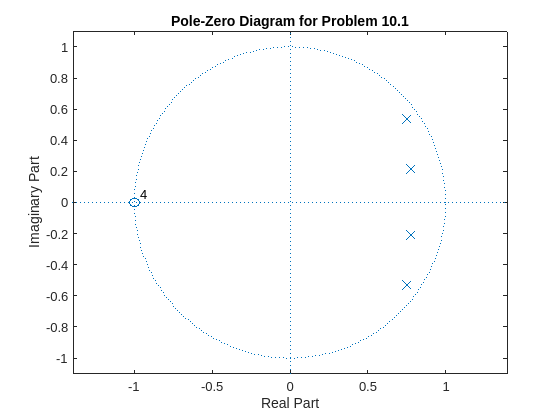

%Now we do the pole/zero diagram!
figure(8);
zplane(numtotal,dentotal);
title('Pole-Zero Diagram for Problem 10.1');